## Tarea 3

## Santiago Fernández Sáenz - C22943 

## Félix Madrigal Mora - C24459

### **Desarrollo**

**1.**

$\texttt{[MATLAB]}$ Considere los siguientes tres algoritmos para obtener la factorización QR de una matriz $$A$$:

- Ortogonalización de Gram-Schmidt (inestable).

- Ortogonalización de Gram-Schmidt (estable).

- Triangularización de Householder.

**a)**

function [Q, R] = qr1(A)

    % Size nos permite obtener las dimensiones de A
    [m, n] = size(A);
    Q = zeros(m, n); % Inicializamos la matriz Q
    R = zeros(n, n); % Inicializamos la matriz R

    for j = 1:n
        % vj se toma como la columna j de la matriz A
        vj = A(:, j); 
        
        for i = 1:j-1
            % Calculamos la proyeccion
            R(i, j) = Q(:, i)' * A(:, j);
            vj = vj - R(i, j) * Q(:, i);
        end

Los resultados de qr1 son:


norma_dif1 = 0.00000000000000077864


        % Normalizar el vector vj para obtener qj

norma_ortogonal1 = 0.00000000000003969087



        R(j, j) = norm(vj);
        Q(:, j) = vj / R(j, j);

Los resultados de qr2 son:


    end

norma_dif2 = 0.00000000000000082808


end

norma_ortogonal2 = 0.00000000000000889229



**b)**

function [Q, R] = qr2(A)

Los resultados de qr3 son:


norma_dif3 = 0.00000000000000717696


    % Size nos permite obtener las dimensiones de A

norma_ortogonal3 = 0.00000000000000178595



    [m, n] = size(A);
    Q = zeros(m, n); % Inicializamos la matriz Q
    R = zeros(n, n); % Inicializamos la matriz R
    V = A;

    for i = 1:n

        R(i, i) = norm(V(:, i));
        Q(:, i) = V(:, i) / R(i, i);

        for j = (i + 1):n

            R(i, j) = Q(:, i)' * V(:, j);
            V(:, j) = V(:, j) - R(i, j) * Q(:, i);
        end
    end
end

**c)**

function [Q, R] = qr3(A)

    % Size nos permite obtener las dimensiones de A

Los resultados de qr1 son:


    [m, n] = size(A);

norma_dif1 de Hilbert = 0.0000000000000008


    Q = zeros(m, n); % Inicializamos la matriz Q

norma_ortogonal1 de Hilbert = 0.0000000000000397



    R = A;
    % Es la matriz de identidad de tamaño mxm

Los resultados de qr2 son:


    M = eye(m);

norma_dif2 de Hilbert = 0.0000000000000008


norma_ortogonal2 = 0.0000000000000089



    for j = 1:n
         

Los resultados de qr3 son:


        x = R(j:m, j);

norma_dif3 de Hilbert = 0.00000000000000717696


        % Creamos el vector e1

norma_ortogonal3 de Hilbert = 0.0000000000000018



        e1 = zeros(length(x), 1);
        e1(1) = 1;

Los resultados de qr de matlab son:


norma_dif de matlab de Hilbert = 0.0000000000000004


        vj = sign(x(1)) * norm(x) * e1 + x;

norma_ortogonal de matlab de Hilbert = 0.0000000000000011



        vj = vj / norm(vj); 
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        M(j:m, :) = M(j:m, :) - 2 * vj * (vj' * M(j:m, :));
    end

    Q = M';
end

**d)**

**¿Se cumple que A = QR?**

Técnicamente si, ya que note que las diferencias dan muy cercanas a 0, la razón por la cual no dan 0 se podría atribuir a alguna inestabilidad del modelo o bien la precisión de la máquina.

**¿Se cumple que Q es ortogonal?**

De nuevo, si, por la misma razón, al calcular la norma ortogonal, los resultados dan muy cercanos a 0.

**Determine si algún algoritmo es mejor que otro.**

En cuanto a precisión es mejor el algoritmo 1, pero en cuanto a aproximar la matriz ortogonal es mejor el algoritmo 3

m = 20;
A = rand(m);
n = 20;
[Q1, R1] = qr1(A);
[Q2, R2] = qr2(A);
[Q3, R3] = qr3(A);


El número de condición es: 17086207555651752.000000000000


norma_dif1 = norm(A - Q1* R1);
norma_dif2 = norm(A - Q2 * R2);
norma_dif3 = norm(A -Q3 * R3);

norma_ortogonal1 = norm(Q1* Q1' -eye(m));
norma_ortogonal2 = norm(Q2 * Q2' - eye(m));
norma_ortogonal3 = norm(Q3 *Q3' -eye(m));

fprintf('Los resultados de qr1 son:\n');
fprintf('norma_dif1 = %.20f\n', norma_dif1);
fprintf('norma_ortogonal1 = %.20f\n\n', norma_ortogonal1);

fprintf('Los resultados de qr2 son:\n');
fprintf('norma_dif2 = %.20f\n', norma_dif2);
fprintf('norma_ortogonal2 = %.20f\n\n', norma_ortogonal2);

fprintf('Los resultados de qr3 son:\n');
fprintf('norma_dif3 = %.20f\n', norma_dif3);
fprintf('norma_ortogonal3 = %.20f\n\n', norma_ortogonal3);

**e)**

m = 20;
A = hilb(m);
n = 20;
[Q1, R1] = qr1(A);
[Q2, R2] = qr2(A);

El error de resolver el sistema de ecuaciones con la factorización PA = LU es: 0.575664393204


[Q3, R3] = qr3(A);
[Qm, Rm] = qr(A);

norma_dif1_H = norm(A - Q1 * R1);
norma_dif2_H = norm(A - Q2 * R2);
norma_dif3_H = norm(A - Q3 * R3);
norma_dif_m = norm(A - Qm * Rm);

norma_ortogonal1_H = norm(Q1 * Q1' - eye(m));
norma_ortogonal2_H = norm(Q2 * Q2' - eye(m));
norma_ortogonal3_H = norm(Q3 * Q3' - eye(m));
norma_ortogonal_m = norm(Qm * Qm' - eye(m));

El error de resolver el sistema de ecuaciones con la factorización QR es: 0.031158124701



fprintf('Los resultados de qr1 son:\n');
fprintf('norma_dif1 de Hilbert = %.16f\n', norma_dif1);
fprintf('norma_ortogonal1 de Hilbert = %.16f\n\n', norma_ortogonal1);

fprintf('Los resultados de qr2 son:\n');
fprintf('norma_dif2 de Hilbert = %.16f\n', norma_dif2);
fprintf('norma_ortogonal2 = %.16f\n\n', norma_ortogonal2);

fprintf('Los resultados de qr3 son:\n');
fprintf('norma_dif3 de Hilbert = %.20f\n', norma_dif3);
fprintf('norma_ortogonal3 de Hilbert = %.16f\n\n', norma_ortogonal3);

El error de resolver el sistema de ecuaciones con la factorización de Cholesky es: 0.592178447984



fprintf('Los resultados de qr de matlab son:\n');
fprintf('norma_dif de matlab de Hilbert = %.16f\n', norma_dif_m);
fprintf('norma_ortogonal de matlab de Hilbert = %.16f\n\n', norma_ortogonal_m);

En este caso es difícil decidir que algoritmo es mejor, ya que el primero se podría clasificar como el peor ya que el error de la norma indica que Q no es ortogonal, sin embargo el algoritmo 2 es mejor en la aproximación a la matriz Hilbert, pero el algoritmo 3 y el algoritmo de Matlab el error de la norma ortogonal da muy pequeño y la aproximación de la matriz es buena pero no mejor que el segundo algoritmo, de igual manera si hubiera que escoger uno creo que lo mejor es el de Matlab ya que obtiene resultados bastante buenos en ambas normas.

**2. ** 

$[\texttt{MATLAB}]$ En esta pregunta se deben usar los comandos de factorización propios de $\texttt{MATLAB} (\texttt{qr(A)}, \texttt{lu(A)}, \texttt{svd(A)}, \texttt{chol(A)})$. Defina $\texttt{m=12}$, $\texttt{x = ones(m,1)}$, $\texttt{A = hilb(m)}$, $\texttt{b = A*x}$. Buscamos resolver el sistema de ecuaciones $$Ax=b$$ mediante estas factorizaciones. Note que la solución exacta es $$x=[1,\ldots,1]^T$$ y denotamos por $$\hat{x}$$ la solución aproximada numéricamente.

Inicialmente, definimos las variables solicitadas.

format long
m = 12;
x = ones(m, 1);
A = hilb(m);
b = A * x;

**a)**

Para ver el número de condición, se tiene lo siguiente:

condicion = cond(A);
fprintf('El número de condición es: %.12f\n', condicion);

El número de condición de una matriz indica el nivel de presición al resolver un sistema de ecuaciones $$Ax=b$$, en particular, se puede afirmar que el resultado anterior es alto debido a que el número de condición de la matriz $A$ posee 17 dígitos no decimales, por lo cual, esto indica que se perderá presición de salida al resolver el sistema de ecuaciones.

Con los casos a resolver a continuación, es importante recordar que los algoritmos estudiados en clase (QR, Cholesky y descomposición en valores singulares) son estables hacia atrás, entonces, por teorema, su error relativo es de orden:


$$O(\varepsilon_m \cdot K(x))$$


en donde $\varepsilon_m$ es la presición de la máquina y $K(x)$ el número de condición.

En el caso de la factorización LU es aún más grave, pues hay que añadir un factor de crecimiento al error relativo:


$$O(\varepsilon_m \cdot K(x) \cdot 2 ^ {m - 1})$$


En donde $m$ es la cantidad de filas en una matriz cuadrada, es decir, para el caso concreto que se desarrolla en este ejercicio, el error relativo es de orden:


$$O(\varepsilon_m \cdot K(x) \cdot 2 ^ {11})$$


**b)**

Calculamos la factorización correspondiente:

[L, U, P] = lu(A);

Resolvemos el sistema de ecuaciones, como:


$$PA = LU \wedge Ax = b$$



$$\Longrightarrow P A x = P b$$


entonces, para calcular el error ocupamos de la función [norm](https://la.mathworks.com/help/matlab/ref/norm.html), se sigue que el resultado es:

% Iniciamos calculando los vectores uno a uno
y = P * b;
y = L \ y;

El error de resolver el sistema de ecuaciones con svd es: 0.004192030253



% Calculamos el sistema
xhat1 = U \ y;

% Obtenemos el error
error_palu = norm((x - xhat1), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización PA = LU es: %.12f\n', error_palu);

**c)**

Procedemos de forma similar con la factorización QR:

% Se calcula la factorización
[Q, R] = qr(A);

% Calculamos el sistema
y = Q \ b;
xhat2 = R \ y;

% Obtenemos el error
error_qr = norm((x - xhat2), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización QR es: %.12f\n', error_qr);

**d)**

Similarmente, con la factorización de Cholesky obtenemos el resultado:

% Factorización de Cholesky
L = chol(A);

% Se calcula el sistema
y = L' \ b;
xhat3 = L \ y;

% Obtenemos el error
error_chol = norm((x - xhat3), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización de Cholesky es: %.12f\n', error_chol);

**e)**

Se procede análogamente con la descomposición en valores singulares, en este caso se requiere la pseudo-inversa de S con la función [pinv](https://la.mathworks.com/help/matlab/ref/pinv.html):


$$A = U S V ^ T \wedge Ax = b$$



$$\Longrightarrow U ^ T A x = U ^ T b$$



$$\Longrightarrow S V ^ T x = U ^ T b$$



$$\Longrightarrow x = V S ^ {-1} U ^ T b$$


% Se calcula la descomposición en valores singulares
[U, S, V] = svd(A);

El error de resolver el sistema de ecuaciones con la aproximación de rango 9 es: 0.000007256911



% Se calcula el término de la derecha
y = U' * b;

   1.0e+09 *

   0.000000000556988
   0.000000002629674
   0.000000022352088
   0.000000268650220
   0.000004290205107
   0.000089578785012
   0.002449553820927
   0.089058213072909
   4.440567693202908
                   0
                   0
                   0



   1.0e+13 *

   0.000000000000056
   0.000000000000263
   0.000000000002235
   0.000000000026865
   0.000000000429021
   0.000000008957879
   0.000000244955382
   0.000008905821293
   0.000444056730330
   0.032140413194454
   3.774182684366420
                   0



% Se obtiene la pseudo-inversa de S
S_inversa = pinv(S);

% El sistema de ecuaciones
xhat4 = V * S_inversa * y;

% Obtenemos el error
error_svd = norm((x - xhat4), 2);
fprintf('El error de resolver el sistema de ecuaciones con svd es: %.12f\n', error_svd);

**f)**

El error es considerablemente grande en todos los casos calculados, sin embargo, al usar la descomposición en valores singulares se obtuvo el menor error de todos los métodos, este se considera aceptable ya que el error muestra una presición de 2 decimales, lo cual es particularmente bueno considerando el número de condición de la matriz A.

**g)**

Calculamos la aproximación de rango 9, para esto se tomó de referencia el código expuesto en el video de SVD Matlab que el profesor otorgó.

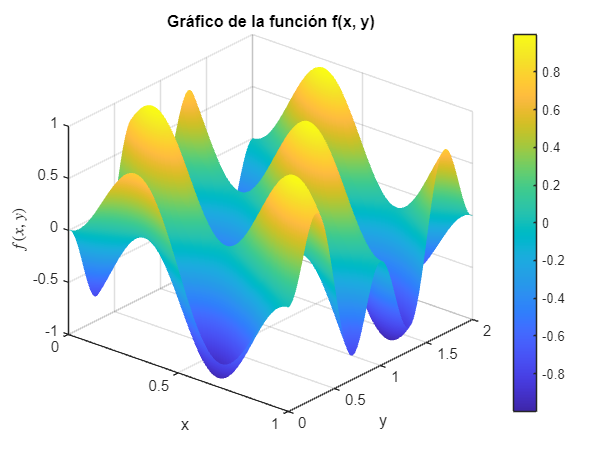

% Obtenemos los valores singulares
valSing = diag(S);

% Definimos la aproximación correspondiente
rango_aprox = 0;

% Iteramos para obtener el rango deseado
for i = 1:9
    rango_aprox = rango_aprox + (valSing(i) * U(:, i) * V(:, i)');
end

% Ahora, extraemos los valores singulares de la aproximación de rango mayor
[U_aprox, S_aprox, V_aprox] = svd(rango_aprox);

% Obtenemos el primer término
y = U_aprox' * b;

% Se obtiene la pseudo-inversa de S
S_inversa = pinv(S_aprox);


% El sistema de ecuaciones
xhat_rango = V_aprox * S_inversa * y;

% Obtenemos su error
error_rango = norm((x - xhat_rango), 2);
fprintf('El error de resolver el sistema de ecuaciones con la aproximación de rango 9 es: %.12f\n', error_rango);

El error mejora significativamente con la aproximación de rango 9, este ofrece una presición de 5 decimales, lo cual supera a todos los métodos probados anteriormente. Esto se debe a los resultados de la reducción del rango en los valores singulares:

% Comprobamos los valores singulares de las 2 matrices
disp(diag(pinv(S_aprox)));
disp(diag(pinv(S)));

Debido al número de condición de la matriz A, sabemos que esta resulta en una pérdida de presición importante, lo cual se reduce al bajar el rango de la matriz, pues se "eliminan" los valores singulares más grandes de la matriz original, siendo sustituidos por 0 debido a la aproximación, esto crea mayor presición a la hora de calcular la svd, lo cual resulta en una reducción del error.

**3. **

Para graficar una función en dos variables $$z=f(x,y)$$, se puede generar una malla (matriz) de puntos $$\texttt{xx,yy}$$ en las cuales se evalúa $$f$$. De esta forma, $$\texttt{zz = f(xx,yy)}$$ es una matriz del mismo tamaño de $$\texttt{xx}$ y $\texttt{yy}$$.

**a)**

% Vectores
x = linspace(0, 1, 100);
y = linspace(0, 2, 200);

% Malla de puntos equidistantes
[xx, yy] = meshgrid(x, y);

% definimos la funciona dada para poder graficar
f = @(x, y) sin(2*pi*(x+y)) .* sin(pi*(x-y));


figure;
surf(xx, yy, f(xx, yy));
% Aplica un sombreado mas suave
shading interp; 
% Se encarga de agregar una barra de colores para hacer alusión a los valores
colorbar; 
% Permite manipular el angulo de la vista
view(40, 30); 
xlabel('x' );
ylabel('y');
zlabel('$f(x, y)$', 'Interpreter', 'latex');
title('Gráfico de la función f(x, y)'); 
grid on;

**b) **

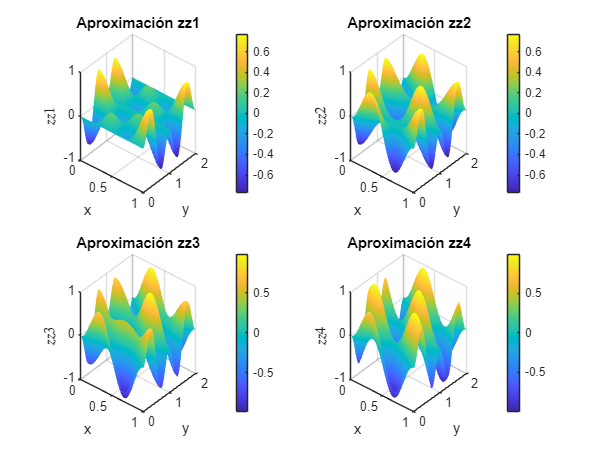

% Matriz
zz = f(xx, yy);

% Realizamos la descomposición en valores singulares y se guardan
[U, S, V] = svd(zz);
valsing = diag(S);

% Se calculan las aproximaciones de los 4 rangos pedidos
zz1 = valsing(1) * U(:, 1) * V(:, 1)';
zz2 = zz1 + valsing(2) * U(:, 2) * V(:, 2)';
zz3 = zz2 + valsing(3) * U(:, 3) * V(:, 3)';
zz4 = zz3 + valsing(4) * U(:, 4) * V(:, 4)';

figure;
subplot(2, 2, 1);
surf(xx, yy, zz1);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz1$', 'Interpreter', 'latex');
title('Aproximación zz1'); 
grid on;


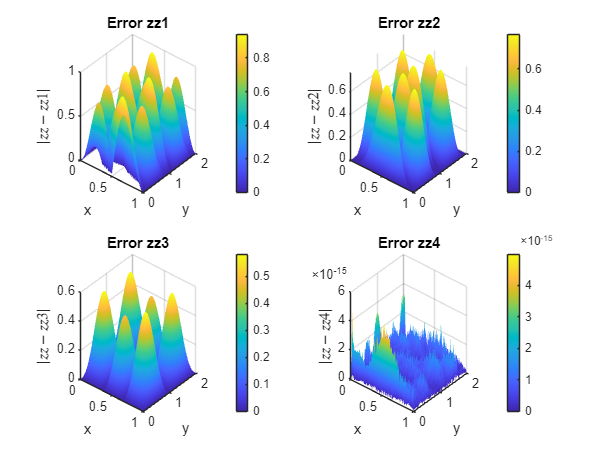

subplot(2, 2, 2);
surf(xx, yy, zz2);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz2$', 'Interpreter', 'latex');
title('Aproximación zz2'); 
grid on;

subplot(2, 2, 3);
surf(xx, yy, zz3);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz3$', 'Interpreter', 'latex');
title('Aproximación zz3'); 
grid on;

subplot(2, 2, 4);
surf(xx, yy, zz4);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz4$', 'Interpreter', 'latex');
title('Aproximación zz4'); 
grid on;

% Ahora graficamos el error absoluto
figure;
subplot(2, 2, 1);
surf(xx, yy, abs(zz - zz1));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz1|$', 'Interpreter', 'latex');
title('Error zz1'); 
grid on;


subplot(2, 2, 2);
surf(xx, yy, abs(zz - zz2));
shading interp;
colorbar;

     4



view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz2|$', 'Interpreter', 'latex');
title('Error zz2');
grid on;

subplot(2, 2, 3);
surf(xx, yy, abs(zz - zz3));
shading interp;
colorbar;

   35.7919
   35.4410
   35.0901
   35.0901
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000

view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz3|$', 'Interpreter', 'latex');
title('Error zz3');
grid on;

subplot(2, 2, 4);
surf(xx, yy, abs(zz - zz4));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz4|$', 'Interpreter', 'latex');
title('Error zz4');
grid on;

Conforme el rango se incrementa se puede notar una mejora en la aproximación, llegando prácticamente al mismo grafico de la función en el rango 4. Además en los gráficos de los errores absolutos ocurre algo similar, conforme se aumenta el rango el error va disminuyendo ya que la aproximación cada vez es mejor, de igual manera todos los errores son bastante pequeños por lo que se obtiene una buena aproximación mediante la descomposición en valores singulares.

**c)**

El rango de $zz$ se puede obtener usando rank

disp(rank(zz));

Podemos comprobar que se cumpla que es de rango 4 numéricamente y ademas obtener los valores singulares que se piden

%creamos un vector fila sobre el cual vamos a iterar, es del tamaño de la
%cantidad de valores singulares mayores a 0
rango = ones(1, sum(valsing > 0));

for j = 1:length(rango)
    if valsing(j) > 0
        rango(j) = valsing(j);
    end
end
disp(valsing)

Entonces note que los valores singulares obtenidos solo hay 4 positivos los demás son muy pequeños por lo que en este caso al ser numéricamente se podría considerar que son 0 ya que se acerca a la precisión de la maquina y la aproximación es bastante buena, así podemos asegurar que es de rango 4 es decir solo tenemos 4 valores singulares, los otros son 0.

**d)**

Dada la función:


$$\[ f(x, y) = \sin(2\pi(x + y)) \sin(\pi(x - y)) \]$$


Podemos reescribirla de la siguiente manera:


$$\[ f(x, y) = \frac{1}{2} [\sin(2\pi x)\cos(2\pi y) + \cos(2\pi x)\sin(2\pi y)] \cdot \frac{1}{2} [\sin(\pi x)\cos(\pi y) - \cos(\pi x)\sin(\pi y)] \]
$$


Expandimos el producto de las expresiones y obtenemos


$$
\sin(2\pi x)\cos(2\pi y)\sin(\pi x)\cos(\pi y) - \sin(2\pi x)\cos(2\pi y)\cos(\pi x)\sin(\pi y) \\ 
 + \cos(2\pi x)\sin(2\pi y)\sin(\pi x)\cos(\pi y) - \cos(2\pi x)\sin(2\pi y)\cos(\pi x)\sin(\pi y)
$$


Sin embargo, aún falta un paso para asegurar que $\( U \)$ y $\( V \)$ sean ortogonales,


$$\[ \|\sin(2\pi x)\sin(\pi x)\| \|\cos(2\pi y)\cos(\pi y)\|  \cdot \frac{\sin(2\pi x)\sin(\pi x)}{\|\sin(2\pi x)\sin(\pi x)\|} \cdot \frac{\cos(2\pi y)\cos(\pi y)}{\|\cos(2\pi y)\cos(\pi y)\|} \] 
+
\[ \|\cos(2\pi x)\cos(\pi x)\| \|\sin(2\pi y)\sin(\pi y)\|  \cdot  \frac{\cos(2\pi x)\cos(\pi x)}{\|\cos(2\pi x)\cos(\pi x)\|} \cdot \frac{\sin(2\pi y)\sin(\pi y)}{\|\sin(2\pi y)\sin(\pi y)\|} \]
-
\[ \|\sin(2\pi x)\cos(\pi x)\| \|\cos(2\pi y)\sin(\pi y)\| \cdot  \frac{\sin(2\pi x)\cos(\pi x)}{\|\sin(2\pi x)\cos(\pi x)\|} \cdot \frac{\cos(2\pi y)\sin(\pi y)}{\|\cos(2\pi y)\sin(\pi y)\|} \]
-
\[ \|\cos(2\pi x)\sin(\pi x)\| \|\sin(2\pi y)\cos(\pi y)\| \cdot  \frac{\cos(2\pi x)\sin(\pi x)}{\|\cos(2\pi x)\sin(\pi x)\|} \cdot \frac{\sin(2\pi y)\cos(\pi y)}{\|\sin(2\pi y)\cos(\pi y)\|} \]$$


De esta manera, podemos ver que $\( f(x, y) \)$ se expresa como la suma de $4 $términos, donde cada uno está dado por $\sigma_i \cdot U_i  \cdot V_i^T$ y se expresan como:


$$\sigma_i = ||\cdot || ||\cdot || \\
U_i :\frac  \text{Expresión trigonométrica}{ ||\cdot || ||\cdot ||} \\ 
V_i :\frac  \text{Expresión trigonométrica}{ ||\cdot || ||\cdot ||} \\ 
 i \in \{1, 2, 3, 4\}$$


De esta manera, podemos ver que $\( zz \)$ es una matriz de rango 4 con solamente 4 valores singulares positivos.

**4. **

Sea $$$p(x) = c_0+c_1x+\ldots+c_{n-1}x^{n-1},\ x\in [0,1].$$$ Considere el problema de minimizar $$$E(c_0,\ldots,c_{n-1}) := \| f - p\|_2^2 = \int_0^1 \vert f(x)-p(x)\vert^2\ dx\rightarrow \min.$$$

**a)**

Tenemos la expresión:


$$\Longrightarrow E(c_0, c_1, \ldots, c_n)  = \| f - p\|_2^2$$



$$\Longrightarrow E(c_0, c_1, \ldots, c_n)  = \int_0^1 |f(x) - p(x)|^2 \, dx$$


Usando la definición de $p(x)$ del inciso, se puede reescribir lo anterior de forma que:


$$E(c_0, c_1, \ldots, c_n)  = \int_0^1 \left( f(x) - \sum_{i=0}^{n-1} c_i \cdot x^i \right)^2 \, dx$$


Con esto, se puede obtener la derivada parcial de cualquier constante $c_i$ de la siguiente manera: 


$$\frac{\partial E}{\partial c_j} 
= \frac{\partial}{\partial c_j} \int_0^1  \left( f(x) - \sum_{i=0}^{n-1} c_i \cdot x^i \right)^2 \, dx \hspace{0.5cm} j \in \{0, 1, \dots, n-1\}$$


Expandimos la expresión:


$$=  \int_0^1 \frac{\partial}{\partial c_j} \left( f(x)^2 
- 2 \cdot f(x) \cdot \sum_{i=0}^{n-1} c_i \cdot x^i  
+ \left( \sum_{i=0}^{n-1} c_i \cdot x^i \right)^{2}  \right) \, dx 
$$


Se distribuye la derivada parcial:


$$= \int_0^1 \frac{\partial}{\partial c_j} ( f(x)^2) \, dx  
- 2 \cdot \int_0^1 \frac{\partial}{\partial c_j} \left( f(x) \cdot \sum_{i=0}^{n-1} c_i \cdot x^i \right) \, dx
+ \int_0^1 \frac{\partial}{\partial c_j} \left( \sum_{i=0}^{n-1} c_i \cdot x^i \right)^{2}  \thinspace dx 

$$


Posteriormente, del primer término, note que:


$$\frac{\partial}{\partial c_j} ( f(x)^2) = 0$$


este no tiene una constante $c_j$.

Del segundo término:


$$\frac{\partial}{\partial c_j} \left( f(x) \cdot \sum_{i=0}^{n-1} c_i x^i \right) = 0 \cdot \sum_{i=0}^{n-1} c_i \cdot x^i  + f(x) \cdot x^j$$



$$\Longrightarrow \frac{\partial}{\partial c_j} \left( f(x) \cdot \sum_{i=0}^{n-1} c_i x^i \right) = f(x) \cdot x^j$$


Y del último término, usando regla de la cadena:


$$\frac{\partial}{\partial c_j} \left( \sum_{i=0}^{n-1} c_i \cdot x^i \right)^{2} = 2 \cdot \sum_{i=0}^{n-1} c_i \cdot x^i \cdot x^{j}$$



$$\frac{\partial}{\partial c_j} \left( \sum_{i=0}^{n-1} c_i \cdot x^i \right)^{2} = 2 \cdot \sum_{i=0}^{n-1} c_i \cdot x^{i + j}$$


Finalmente, juntando los 3 términos:


$$ = 0 -2 \int_0^1 f(x) \cdot x^j \, dx +  2 \cdot \sum_{i=0}^{n-1} c_i \cdot \int_0^1 x^{i + j} \, dx

$$


Finalmente, igualamos la expresión anterior a 0 para sus puntos críticos:


$$-2 \cdot \int_0^1 f(x) \cdot x^j \, dx +  2 \cdot \sum_{i=0}^{n-1} c_i \cdot \int_0^1 x^{i + j} \, dx = 0$$



$$\Longrightarrow  2 \cdot \sum_{i=0}^{n-1} c_i \cdot \int_0^1 x^{i + j} \, dx = 2 \cdot \int_0^1 f(x) \cdot x^j \, dx$$



$$\Longrightarrow \sum_{i=0}^{n-1} c_i \cdot \int_0^1 x^{i + j} \, dx = \int_0^1 f(x) \cdot x^j \, dx$$


Lo cual puede expresarse de la forma $\textrm{Mc}=b$.

El problema de este sistema es que, debido a la cantidad de términos de la sumatoria, para valores grandes de $n$ crece la expresión:


$$\frac{\| \widetilde{f}(x) - f(x) \|}{\|f(x)\|}$$


lo cual aumenta el error del sistema, llegando incluso, en cierto punto, a volverse inestable.

**b)**

La solución del sistema se presenta a continuación: 

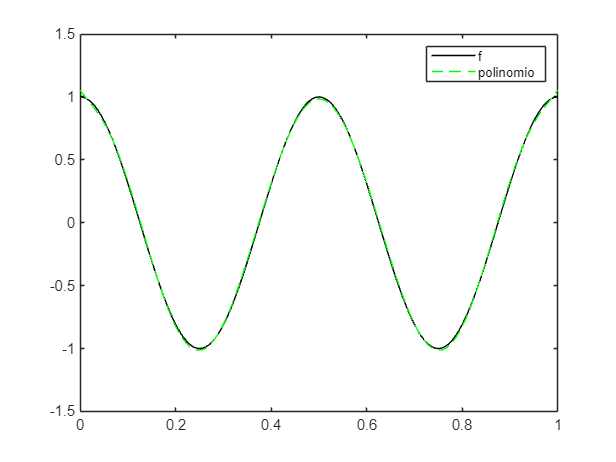

n = 10;

% Función del inciso
f = @(x) cos(4 * pi * x);

% Variables para el sistema correspondiente
vector_b = zeros(n, 1);
matriz_M = zeros(n, n);

% Ciclo para llenar las variables
for i = 1:n
    for j = 1:n
        matriz_M(i, j) = integral(@(x) x.^(i-1 + j-1), 0, 1);
    end
    vector_b(i) = integral(@(x) f(x) .* x.^(i-1), 0, 1);

end

% Se obtienen las constantes necesarias con sustitución hacia atrás
c = matriz_M \ vector_b;

El error es: 0.0001733766275900



% Se obtiene el polinomio con las constantes correspondientes
polinomio = @(x) polyval(flip(c'), x);

El gráfico y el error son los siguientes:

% Valores de x
xx = linspace(0, 1, 1000);

% Gráfico correspondiente
figure;
plot(xx, f(xx), 'k', 'DisplayName', 'f');
hold on;
plot(xx, polinomio(xx), 'g--', 'DisplayName', 'polinomio');
legend;
hold off;

% Error del polinomio
error1 = integral(@(x) ((f(x) - polinomio(x)).^2), 0, 1);
fprintf('El error es: %.16f\n', error1);

**c)**

Usando los polinomios de Legendre, se tiene la siguiente aproximación.

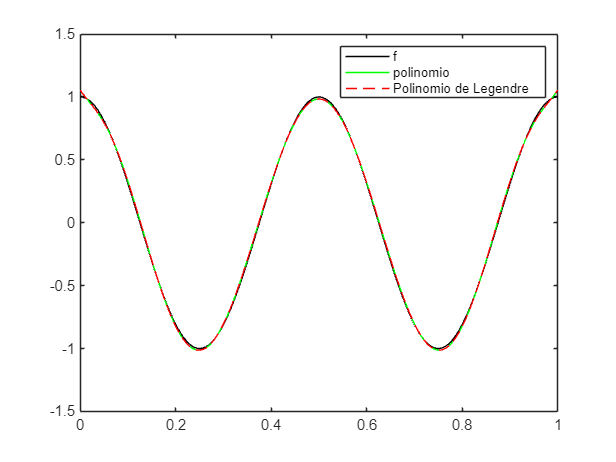

% Se guardan, como funciones, los primeros 2 phi en [0, 1]
phi = cell(n, 1);
phi{1} = @(x) ones(size(x));
phi{2} = @(x) 2 * x - 1;

% Se obtienen, de manera recursiva, los phi_k
for i = 3:n
    phi{i} = @(x) ((2 * (i - 1) - 1) * (2 * x - 1) .* phi{(i - 1)}(x) - (i - 2) * phi{i - 2}(x)) / (i - 1);
end

% Vector para los beta_k
betak = zeros(n, 1);

% Obtenemos los coeficientes
for j = 1:n
    % Obtenemos el numerador
    numerador = integral(@(x) f(x) .* phi{j}(x), 0, 1, 'AbsTol', 1e-12, 'RelTol', 1e-12);

    
    % Obtenemos el denominador
    denominador = integral(@(x) phi{j}(x).^2, 0, 1, 'AbsTol', 1e-12, 'RelTol', 1e-12);
    

El error con polinomios de Legendre es: 0.0001733766269292


    % Guardamos beta_k
    betak(j) = numerador / denominador;
end

% Función para el polinomio de Legendre
poly_leg = @(x) zeros(size(x));

% Se obtiene, iterativamente, el polinomio con n=10
for k = 1:n
    poly_leg = @(x) poly_leg(x) + betak(k) * phi{k}(x);
end

% Gráfico con el polinomio de Legendre
figure;
plot(xx, f(xx), 'k', 'DisplayName', 'f');
hold on;
plot(xx, polinomio(xx), 'g-', 'DisplayName', 'polinomio');
hold on;
plot(xx, poly_leg(xx), 'r--', 'DisplayName', 'Polinomio de Legendre');
legend;
hold off;

% Error con polinomios de Legendre
error2 = integral(@(x) ((f(x) - poly_leg(x)).^2), 0, 1, 'AbsTol', 1e-12, 'RelTol', 1e-12);
fprintf('El error con polinomios de Legendre es: %.16f\n', error2);

**5.**

Si $$u, v \in \mathbb{R}^m$$, la matriz$ $A=I+u v ^ T$$ es llamada $\textit{perturbación de rango uno de la identidad}$

**a)**

Para encontrar $\alpha$, considere, por definición:


$$A ^ {-1} \cdot A = I$$



$$\Longrightarrow (I + u \cdot v ^ T) \cdot (I + \alpha \cdot u \cdot v ^ T) = I$$



$$\Longrightarrow I + \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + u \cdot v ^ T \cdot \alpha \cdot u \cdot v ^ T= I$$



$$\Longrightarrow  \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + u \cdot v ^ T \cdot \alpha \cdot u \cdot v ^ T = 0$$


Como $\alpha $ es un escalar, se puede mover del último término:


$$\Longrightarrow  \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + \alpha \cdot u \cdot v ^ T \cdot  u \cdot v ^ T = 0$$


Ahora, note que $v_{1 \times m} ^ {T}$ y $u_{m \times 1}$, entonces $(v ^ T \cdot u)_{1 \times 1}$, es decir, ese producto es un escalar, por lo que se puede mover ese término igualmente:


$$\Longrightarrow  \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + \alpha \cdot  (v ^ T \cdot  u) \cdot u \cdot v ^ T = 0$$



$$\Longrightarrow u \cdot v ^ {T} (\alpha + 1 + \alpha \cdot  (v ^ T \cdot  u)) = 0$$



$$\Longrightarrow \alpha + 1 + \alpha \cdot  (v ^ T \cdot  u) = (u \cdot v ^ {T}) ^ {-1} \cdot 0$$



$$\Longrightarrow \alpha + 1 + \alpha \cdot  (v ^ T \cdot  u) = 0$$



$$\Longrightarrow \alpha + \alpha \cdot  (v ^ T \cdot  u) = -1$$



$$\Longrightarrow \alpha \cdot (1 + v ^ T \cdot  u) = -1$$



$$\Longrightarrow \alpha= \frac{-1}{1 + v ^ T \cdot  u}$$


**b)**

Una matriz es singular si esta es cuadrada pero no tiene inversa.

Por el teorema visto en clase, una matriz $A$ es invertible sí y solo sí esta posee rango completo, por lo cual, como $A \in \mathbb{M}_{m \times m}$, si:


$$rango(A) \neq m$$


A es una matriz singular.

Con esto, el núcleo de A depende de su rango, si A es de rango completo:


$$ker(A) = \left[
\begin{array}{llllll}
0  \\ 
0  \\
0  \\
\vdots \\ 
0
\end{array} \right]_{m \times 1}$$


de lo contrario, el núcelo de A tiene más de una solución, en particular, para que $A$ no sea invertible se debe indefinir $\alpha$:


$$\alpha = \frac{-1}{1 + v ^ T \cdot  u}$$


Esta se indefine si:


$$v ^ T \cdot  u = -1$$


pues el denominador sería equivalente a 0.

Ahora, para el núcleo, considere el sistema:


$$A \cdot x = 0$$



$$\Longrightarrow (I + u \cdot v ^ T) \cdot x = 0$$



$$\Longrightarrow x + u \cdot v ^ T \cdot x = 0$$


Y note que $v_{1 \times m} ^ {T}$ y $x_{m \times 1}$, por lo que $(v^ {T} \cdot x)_{1 \times 1}$ es un escalar al que llamaremos $\beta$, entonces:


$$\Longrightarrow x + u \cdot \beta = 0$$



$$\Longrightarrow x = - u \cdot \beta$$


lo cual corresponde a la solución del sistema $A \cdot x = 0$, es decir, es parte del núcleo de $A$

**6.**

Dada $$A = U\Sigma V^T \in\mathbb{R}^{m\times n}$$ una descomposición en valores singulares de $$A$$, defina su pseudoinversa como $$A^+ = V \Sigma^+ U^T$$, donde $$\Sigma^+$$ se obtiene de $$\Sigma$$ al invertir sus entradas no nulas; esto es $$(\Sigma^+)_{ii} = 1/\sigma_{ii}$ si $\sigma_{ii}>0$$. Demuestre que si $$x$$ está en el espacio fila de $$A$$ y $$y=A x$$ entonces $$x = A^+y$$.

Dado que $x$ esta en el vector fila, podemos expresarlo como


$$x = \sum_{i=1}^r B_i v_i.$$


Luego tenemos que $$y = Ax$$ y reemplazando:


$$
    y = \sum_{i=1}^r \sigma_i u_i v_i^T \sum_{j=1}^r B_j v_j.
$$


Redistribuyendo la expresión ya que $v_i^T$ y $v_j$ son un producto escalar y debido a que son ortogonales podemos reacomodarlo vamos a obtener:


$$
    y = \sum_{i=1}^r \sigma_i u_i \sum_{j=1}^r B_j (v_i^T v_j).
$$


Como $$v_i^T v_j = 0$$ si $$i \neq j$$ por ser ortogonales, la expresión se simplifica a:


$$

    y = \sum_{i=1}^r \sigma_i u_i B_i.
$$


Ahora debemos ver que $$x = A^+ y$$, de igual manera sabemos que


$$A^+ = \sum_{k=1}^r v_k \frac{1}{\sigma_k} u_k^T.$$


Entonces remplazando tanto $A^+ $ como $y$ vamos a obtener que


$$x = \sum_{k=1}^r v_k \frac{1}{\sigma_k} u_k^T \left( \sum_{i=1}^r \sigma_i u_i B_i \right)$$


Y nuevamente repitiendo el paso que se había hecho anteriormente pero ahora con $u_k^T$ y $u_i$ podemos simplificar la expresión y obtener:


$$x = \sum_{k=1}^r v_k B_k$$


Esto es cierto, pues es la definición de $$x$$ en el vector fila que se mencionó al principio.

Por lo tanto, se cumple que:


$$x = A^+ y.$$


**7.**

Considere un conjunto de mediciones $$\lbrace (x_i,y_i)\rbrace_{i=1}^m$$. En este ejercicio deseamos resolver el problema de mínimos cuadrados, donde la función buscada $$f(x,c)$$ no depende linealmente de los coeficientes $$c = [c_1,\ldots,c_n]^T\in\mathbb{R}^n$$ (en clase analizaremos el caso donde $$f$$ es un polinomio). De esta forma, deseamos hallar $c$ tal que $$$\sum_{i=1}^m \vert f(x_i,c) - y_i\vert^2\rightarrow\min$$ $.

Primero debemos definir la funcion con la cual vamos a trabajar y sus valores exactos

function fxc = fxc(x,c)
    fxc = c(1)* exp(-c(2)* x) .* sin(c(3) * x + c(4));
end

c_exactos = [1; 1/2; 2; 0];

`a)`

load('data.mat');
%debemos ordenar los datos para poder graficar la funcion correctamente
[x, idx] = sort(x);
y = y(idx);

**b)**

Primero realizamos la funcion que calcule el jacobiano

function Jacob = Jacobiano(x, c)
    %creamos la matriz correspondiente
    Jacob = zeros(length(x), 4);
    %calculamos la derivada parcial en cada cj
    Jacob(:, 1) = exp(-c(2) * x) .* sin(c(3) * x + c(4));

Número de iteraciones: 6


    Jacob(:, 2) = -c(1) * x .* exp(-c(2) * x) .* sin(c(3) * x + c(4));
    Jacob(:, 3) = c(1) * exp(-c(2) * x) .* x .* cos(c(3) * x + c(4));
    Jacob(:, 4) = c(1) * exp(-c(2) * x) .* cos(c(3) * x + c(4));
end

Ahora implementamos el algoritmo

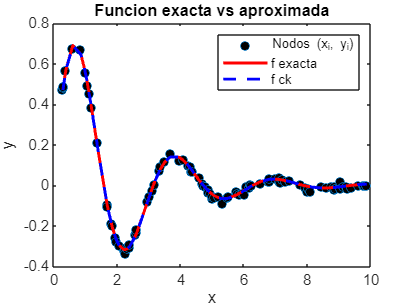


function [ck, k, normas_ck, num_condicion] = min_cuadrados(x, y, c0)
    % Inicialización
    max_iteraciones = 100;
    tol = 1e-8;
    ck = c0;
    normas_ck = zeros(1, max_iteraciones);
    num_condicion = zeros(1, max_iteraciones);

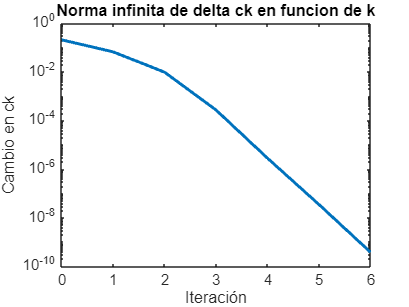


    % gck es el valor de la función f evaluado en ck
    gck = fxc(x, ck);
    % Jck es el valor del Jacobiano evaluado en ck
    Jck = Jacobiano(x, ck);

    % vamos a resolver delta c usando la pseudoinversa

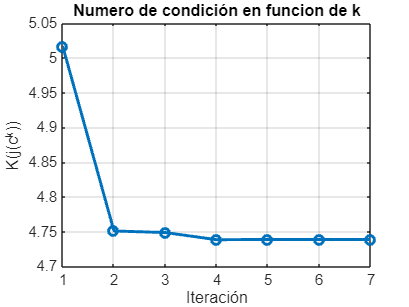

    delta_c = (Jck' * Jck) \ (Jck' * (y - gck));
    
    % Guardar la primera norma y condición
    normas_ck(1) = norm(delta_c, Inf);
    num_condicion(1) = cond(Jck);

    k = 0;
    while normas_ck(k+1) > tol && k < max_iteraciones
        % Actualizar los parámetros
        ck = ck + delta_c;

        gck = fxc(x, ck);
        Jck = Jacobiano(x, ck);
        
        % Calcular delta_c nuevamente

        delta_c = (Jck' * Jck) \ (Jck' * (y - gck));


Número de iteraciones: 8


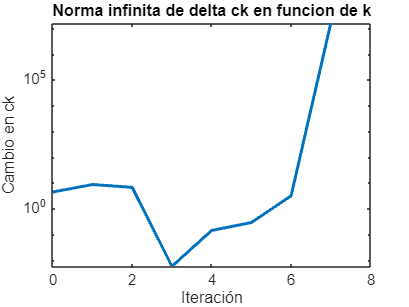

        % Aumentar el contador
        k = k + 1;
        % Guardar la norma y condición
        normas_ck(k+1) = norm(delta_c, Inf);
        num_condicion(k+1) = cond(Jck);
    end


    %Redimensionamos para tener el tamaño correcto
    normas_ck = normas_ck(1:k+1);
    num_condicion = num_condicion(1:k+1);
end

**c)**

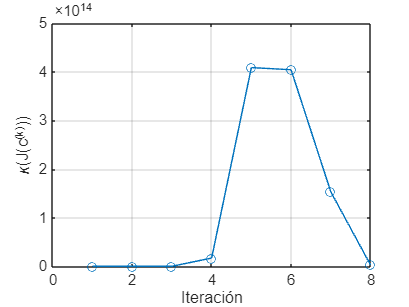

c0 = [1.1; 0.4; 2.1; 0.2];

%se ejecuta el algoritmo con los nuevos c
[ck, k, normas_ck, num_condicion] = min_cuadrados(x, y,c0);

fprintf('Número de iteraciones: %d\n', k);

% Graficamos la funcion excata y aproximada
figure;
plot(x, y, 'o', 'DisplayName', 'Nodos (x_i, y_i)','MarkerFaceColor', 'black');
hold on;
plot(x, fxc(x, c_exactos), 'r-', 'LineWidth',2, 'DisplayName', 'f exacta');
plot(x, fxc(x, ck), 'b--', 'LineWidth',2, 'DisplayName', 'f ck');
legend;
ylabel('y');
xlabel('x');
title('Funcion exacta vs aproximada')
hold off;

% Se grafica la norma infinita en funcion de k
figure;
semilogy(0:k, normas_ck, 'LineWidth', 2);
xlabel('Iteración');
ylabel('Cambio en ck');
title('Norma infinita de delta ck en funcion de k')

Del primer grafico podemos concluir que los valores iniciales son cercanos a función real, ya que se comportan de manera estable y requiere muy pocas iteraciones para llegar a la tolerancia solicitada.

Con respecto al segundo grafico podemos ver que rápidamente las diferencias entre ck se vuelve muy pequeñas lo que es un indicio que el algoritmo cada vez se aproxima más.

**d)**

Ahora vamos a ver el numero de condicion

figure;
plot(num_condicion, '-o', 'LineWidth', 2);
xlabel('Iteración');
ylabel('K(j(c^k))');
title('Numero de condición en funcion de k');
grid on;

El número de condición cada vez disminuye más y tiende a comportarse de una manera estable al final, es un resultado parecido obtenido al del inciso anterior ya que asemeja que cada vez se acerca más a la solución o al menos a una solución que se comporta de manera más estable.

**e)**

c0_nuevo = [1; 1; 1; 1];
[ck, k, normas_ck, num_condicion] = min_cuadrados(x, y,c0_nuevo );

fprintf('Número de iteraciones: %d\n', k);

figure;
semilogy(0:k, normas_ck, 'LineWidth', 2);
xlabel('Iteración');
ylabel('Cambio en ck');
title('Norma infinita de delta ck en funcion de k')

figure;
plotPodemos ver que en este caso la norma diverge, esto puede suceder por varias razones, primero note que se están obteniendo algunos warmings los cuales indican que la matriz del jacobiano no es bien condicionada y puede ser casi singular, lo que puede llevar a errores, además de que el primer valor de ck da prácticamente 0 lo que puede generar que no de una buena aproximación.(1:length(num_condicion), num_condicion, '-o');
xlabel('Iteración');
ylabel('\kappa(J(c^{(k)}))');
grid on;

Podemos ver que en este caso la norma diverge, esto puede suceder por varias razones, primero note que se están obteniendo algunos warmings los cuales indican que la matriz del jacobiano no es bien condicionada y puede ser casi singular, lo que puede llevar a errores, además de que el primer valor de ck da prácticamente 0 lo que puede generar que no de una buena aproximación.

**8)**

Considere un conjunto de $$m+1$$ puntos $$\lbrace (x_i,y_i)\rbrace_{i=0}^m$$, donde:


$$$$0=x_0<x_1<\ldots< x_{m-1}<x_m=1$$$$
 

es una partición del intervalo $$[0,1]$$ (no necesariamente con puntos equidistantes). En particular asumiremos que $$y_0 = y_{m}$$ pues consideraremos funciones periódicas. 

Deseamos construir una función $$s_2:\mathbb{R} \rightarrow \mathbb{R}$$ tal que:

- $$s_2$$ es periódica con periodo $$1$$; esto es, $$s_2(x+1) = s_2(x)\ \forall\ x\in\mathbb{R}$$.

- $$s_2\in C^1(\mathbb{R})$$; esto es, $$s_2$$ tiene derivada continua.

- $$s_2$$ interpola los valores del conjunto de puntos; esto es, $$s_2(x_i) = y_i\ \forall\ i = 0,1,\ldots,m$$.

- La restricción de $$s_2$$ a cada subintervalo $$[x_i,x_{i+1}]\ (i=0,1,\ldots,m-1)$$ es un polinomio cuadrático.

Es claro que basta construir $$s_2$$ en el intervalo $$[0,1]$$ al ser periódica.

**a)**

Se pueden observar las restricciones de $s_2$ en cada subintervalo $[x_i, \hspace{0.1cm} x_{i + 1}]$, para $i \in \{0, \dots, m - 1\}$, tal que:


$$$s_2(x) = \alpha_i + \sigma_i (x-x_i) + \beta_i(x-x_i)^2$ \hspace{0.5cm} \forall i \in \{0, \dots, m\}$$


Inicialmente, para que se cumpla la interpolación, se requiere:


$$s_2(x_i) = y_i \hspace{0.5cm} \forall i \in \{0, \dots, m\}$$
 

con lo cual, llegamos a que:


$$\alpha {\;}_i =y_i$$


con lo que se obtienen las primeras $m + 1$ ecuaciones.

Siguiendo con otra condición: 


$$\( s_2(x) \in C^1([0,1]) \)$$


la derivada de $s_2$ debe ser continua, en particular, debe serlo en cada punto interno $x_i \hspace{0.1cm} i \in \{1, \dots, m - 1\}$, esto ya que los puntos extremos ($x_0 = 0 \wedge x_m = 1$) son irrelevantes para nuestro análisis, pues son parte del polinomio continuo de cada subintervalo. 

Lo anterior se expresa como:


$$\[ s_2'(x_{i}^-) = s_2'(x_{i}^+)$$


con lo cual se obtienen $m - 1$ ecuaciones adicionales.

Luego, como $s_2$ debe ser continua, se tiene que:


$$\[ s_2(x_{i}^-) = s_2(x_{i}^+) \hspace{0.5cm} \forall i \in \{1, \ldots, m-1\}$$


lo que, nuevamente, agrega $m - 1$ ecuaciones.

De momento, se tienen $3m - 1$ ecuaciones, con lo cual, la periodicidad agrega la última, completando las $3m$ ecuaciones.

Con lo anterior, si $x \in [x_i, \hspace{0.1cm} x_{i + 1}]$ entonces: 


$$\[ s_2'(x) = \sigma_i + 2 \cdot \beta_i \cdot (x - x_i) \] $$


Entonces, por la continuidad, se tiene:


$$s_2'(x_i^-) = s_2'(x_i^+) $$
 


$$\Longrightarrow \sigma_{i-1} +2 \cdot \beta_{i-1} \cdot (x_i - x_{i-1}) = \sigma_i$$



$$\Longrightarrow \sigma_{i-1} + 2 \cdot \beta_{i-1} \cdot h_i = \sigma_i \hspace{5cm} (*)$$


Para obtener el valor de ${\beta \;}_{i-1}$, tome:


$$y_i = s_2(x_i^-)$$



$$\Longrightarrow y_i = \alpha_{i-1}  + \sigma_{i-1}(x_i-x_{i-1}) + \beta_{i-1}(x_i- x_{i-1})^2$$


Despejando:


$$\Longrightarrow \beta_{i-1} = \frac{y_i - \alpha_{i-1} - \sigma_{i-1} (x_i - x_{i-1})}{(x_i - x_{i-1})^2} =
\frac{y_i - y_{i-1} - \sigma_{i-1} h_i}{h_i^2}$$



$$\Longrightarrow \beta_{i-1} = \frac{y_i - y_{i-1} - \sigma_{i-1} h_i}{h_i^2}$$


De esta forma, se sustituye $\beta_{i-1}$ en $(*)$ y se obtiene:


$$\sigma_i = \sigma_{i-1} + 2 \cdot h_i \cdot \left(\frac{y_{i} - y_{i-1} - \sigma_{i-1}h_i}{h_i^2}\right)$$



$$\Longrightarrow \sigma_i = \sigma_{i-1} + 2 \cdot \frac{y_{i} - y_{i-1} - \sigma_{i-1}h_i}{h_i}$$



$$\Longrightarrow \sigma_i = \sigma_{i-1} + 2\frac{y_{i} - y_{i-1}}{h_i} -2 \sigma_{i-1}$$



$$\Longrightarrow \sigma_i = 2 \cdot \frac{y_i - y_{i-1}}{h_i} - \sigma_{i-1}$$


$\Longrightarrow \sigma_{i-1} + \sigma_i = 2 \cdot \frac{y_i - y_{i-1}}{h_i}$, $\forall i \in \{0, \dots, m\} \hspace{5cm} (**)$

De esta manera, para determinar los sigmas se tendría que resolver el siguiente sistema de ecuaciones:


$$A \cdot x = b$$



$$\left[
\begin{array}{cccccc}
1 & 1 & 0 & \dots & 0 & 0 \\
0 & 1 & 1 & \dots & 0 & 0 \\
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots \\
0 & 0 & 0 & \dots & 1 & 1 \\
1 & 0 & 0 & \dots & 0 & 1 \\
\end{array}
\right]

\cdot

\left[ \begin{array}{c}
\sigma_0 \\
\sigma_1 \\
\vdots \\
\sigma_{m-1} \\
\sigma_{m} \\
\end{array}
 \right]

= 

\left[ \begin{array}{c}
b_1 \\
b_2 \\
\vdots \\
b_{m} \\
b_{m + 1} \\
\end{array}
 \right]$$


donde $b_i = 2\frac{y_i - y_{i-1}}{h_i}$, $\forall i \in \{1, \dots, m + 1\}$, $A \in \mathbb{R}^{m \times m}$ y $x, b \in \mathbb{R}^m$.

La última fila se explica ya que si se toma un caso particular en $(**)$, en concreto $i = m$, se cumple:


$$\sigma_{m-1} + \sigma_m = 2 \cdot \frac{y_m - y_{m-1}}{h_m}$$


pero como $s$ es periódica, entonces $\sigma_0 = \sigma_m$, por lo que en este caso se tendría que $\sigma_{m-1} + \sigma_0 = 2\frac{y_m - y_{m-1}}{h_m}$.

Finalmente, el sistema de ecuaciones correspondiente a las constantes viene determinado por:


$$\[
\left \{
\begin{array}{rr}
\alpha_i = y_i \\
\space \sigma_{i-1} = 2\frac{y_i - y_{i-1}}{h_i} - \sigma_i \\
\beta_{i-1} = \frac{y_i - y_{i-1} - \sigma_{i-1} h_i}{h_i^2}
\end{array}
\right .
\]$$


**b)**

Con $s_2$, la aproximación de la función se obtiene como sigue:

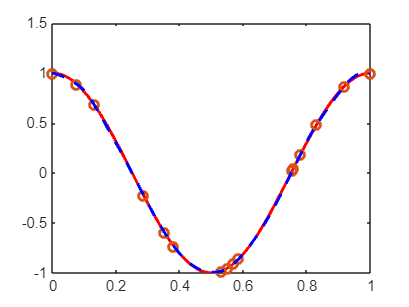

m = 15;

% Función f
f = @(x) cos(2*pi*x);

% Vector x_i con valores aleatorios
xi = sort(rand(m+1, 1))';

% Valores de los extremos del intervalo
xi(1) = 0;
xi(end) = 1;

% Calculamos los y_i
y = f(xi);

% Periodicidad de la función
y(1) = y(end);

% Definimos el vector b
vec_b = zeros(m, 1);

% Llenamos el vector b
for i = 1:m
    vec_b(i) = 2*(y(i+1) - y(i)) / (xi(i+1) - xi(i));
end

% Definimos la matriz A
matriz_A = diag(ones(m, 1)) + diag(ones(m-1, 1), 1);
matriz_A(end, 1) = 1;

% Resolvemos el sistema con sustitución hacia atrás
sigmak = matriz_A \ vec_b;

% Puntos equidistantes entre 0 y 1 para evaluar f y s2
xx = linspace(0, 1);
yy = f(xx);

% Vector con los alpha
alpha = y;

% Creamos el vector de los beta
beta = zeros(1, m);

% Se rellenan los beta
for i = 1:m
    beta(i) = (y(i+1) - y(i) - sigmak(i)*(xi(i+1)-xi(i))) / ...
        ((xi(i+1)-xi(i))^2);
end


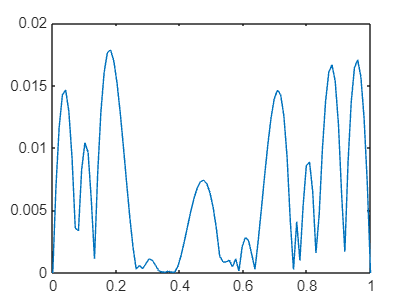

% Creamos el vector de s_2
s2 = zeros(1, length(xx));

% Llenamos s_2

for j = 1:length(xx)
    for i = 1:m 
        if xi(i) <= xx(j) && xx(j) <= xi(i+1)
            s2(j) = alpha(i) + sigmak(i)*(xx(j)-xi(i)) + ...

La norma corresponde a: 0.0178552403772777


                    beta(i)*(xx(j)-xi(i))^2;
        end
    end
end

% Error absoluto
error = abs(yy - s2);

Posteriormente, se construyen los graficos solicitados.

% Graficamos f, s2 y los puntos x_i, y_i
figure;
plot(xx, yy,'r',LineWidth=2);
hold on;
plot(xi, y, 'o',LineWidth=2);
plot(xx, s2,'b--',LineWidth=2);

% Graficamos el error absoluto
figure;
plot(xx, error);

% Estimamos la norma del error
norma_inf = max(error);
fprintf('La norma corresponde a: %.16f\n', norma_inf);

**c)**

Se repite el inciso anterior con los nodos equidistantes.

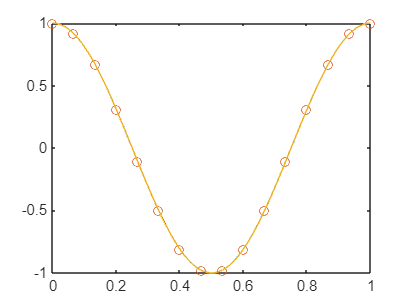

% Nodos equidistantes
xi = linspace(0, 1, m+1)';

% Calculamos los y_i
y = f(xi);

% Recursividad de la función
y(1) = y(end);

% Vector b
vec_b = zeros(m, 1);

% Llenamos el vector b
for i = 1:m
    vec_b(i) = 2 * (y(i+1) - y(i)) / (xi(i+1) - xi(i));
end

% Matriz A
matriz_A = diag(ones(m, 1)) + diag(ones(m-1, 1), 1);
matriz_A(end, 1) = 1;

% Encontramos los sigmas
sigmak = matriz_A \ vec_b;

% Vector con los alpha
alpha = y;

% Inicializamos el vector que tendrá los beta
beta = zeros(1, m);

% Llenamos el vector con los beta
for i = 1:m
    beta(i) = (y(i+1) - y(i) - sigmak(i)*(xi(i+1)-xi(i))) / ...
        ((xi(i+1)-xi(i))^2);
end

% Creamos el vector de s_2

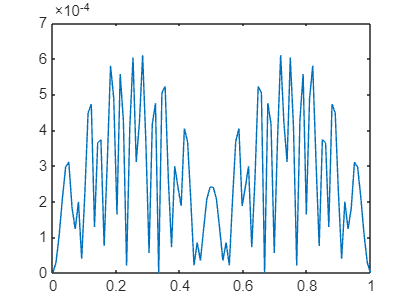

s2 = zeros(1, length(xx));

% Rellenamos s2
for j = 1:length(xx)

    for i = 1:m 
        if xi(i) <= xx(j) && xx(j) <= xi(i+1)
            s2(j) = alpha(i) + sigmak(i)*(xx(j)-xi(i)) + ...
                    beta(i)*(xx(j)-xi(i))^2;

La norma corresponde a: 0.0006098027184256


        end
    end
end

% Error absoluto
error = abs(yy - s2);

En este caso, los gráficos pedidos son los siguientes:

% Graficamos f, s2 y los puntos x_i, y_i
figure;
plot(xx, yy);
hold on;
plot(xi, y, 'o');
plot(xx, s2);

% Graficamos el error absoluto
figure;
plot(xx, error);

% Estimamos la norma del error
norma_inf = max(error);
fprintf('La norma corresponde a: %.16f\n', norma_inf);

La última aproximación, con nodos equidistantes, es considerablemente mejor, esto se observa tanto en los gráficos como en la norma de los últimos 2 incisos. Probablemente, esto sea debido a que los nodos aleatorios concentran información cerca de puntos innecesariamente, pues la función no tiene oscilaciones o comportamientos atípicos, por otro lado, los nodos equidistantes son ideales cuando la función presenta un comportamiento común, como este caso.

**d)**

Utilizando la derivada de las funciones, se llega al siguiente resultado:

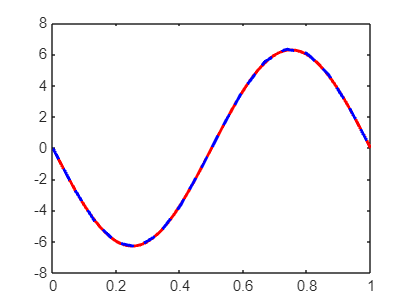

% Derivada de f
f_prima = @(x) -sin(2*pi*x) * 2*pi;

% Imágenes de la derivada
y_prima = f_prima(xx);

% Definimos el vector b
vec_b = zeros(m, 1);

% Llenamos el vector anterior
for i = 1:m
    vec_b(i) = 2*(y(i+1) - y(i)) / (xi(i+1) - xi(i));
end

% Definimos la matriz A
matriz_A = diag(ones(m, 1)) + diag(ones(m-1, 1), 1);
matriz_A(end, 1) = 1;

% Resolvemos el sistema Ax = b para encontrar los sigmas
sigmak = matriz_A \ vec_b;

% Vector con los alpha
alpha = y;

% Vector para guardar los beta
beta = zeros(1, m);

% Sse rellenan los beta
for i = 1:m
    beta(i) = (y(i+1) - y(i) - sigmak(i)*(xi(i+1)-xi(i))) / ...
        ((xi(i+1)-xi(i))^2);
end

% Vector para guardar los s_2 prima
s2_prima = zeros(1, length(xx));

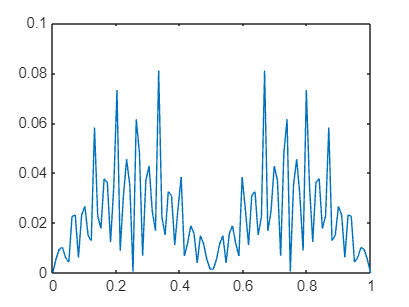


% Construimos la derivada de s2
for j = 1:length(xx)
    for i = 1:m 

        if xi(i) <= xx(j) && xx(j) <= xi(i+1)
            s2_prima(j) = sigmak(i) + 2*beta(i)*(xx(j)-xi(i));
        end
    end

La norma corresponde a: 0.0809833717167407


end

% Error absoluto
error = abs(y_prima - s2_prima);

Los gráficos corresponden a:

% Graficos de f' y s'
figure;
plot(xx, y_prima,'r', LineWidth=2);
hold on;
plot(xx, s2_prima,"b--", LineWidth=2);

% Grafico del error
figure;
plot(xx, error);

% Estimamos la norma del error
norma_inf = max(error);
fprintf('La norma corresponde a: %.16f\n', norma_inf);

Si se quiere aproximar $f \prime$ con una función $s$, una opción es que $s$ sea un spline cúbico natural, para este problema en particular, es importante que $s$ tenga periodo 1, por lo cual, el problema se vuelve análogo al desarrollado al ejercicio 8, con la diferencia de que $s \prime$ ahora consiste de polinomios de grado 2 en cada subintervalo, lo cual permite afirmar que habrá uniones suaves entre los subintervalos, así, su derivada será continua, es decir, $s \prime \prime \in C^2([0,1]) \)$, por lo que es continua.